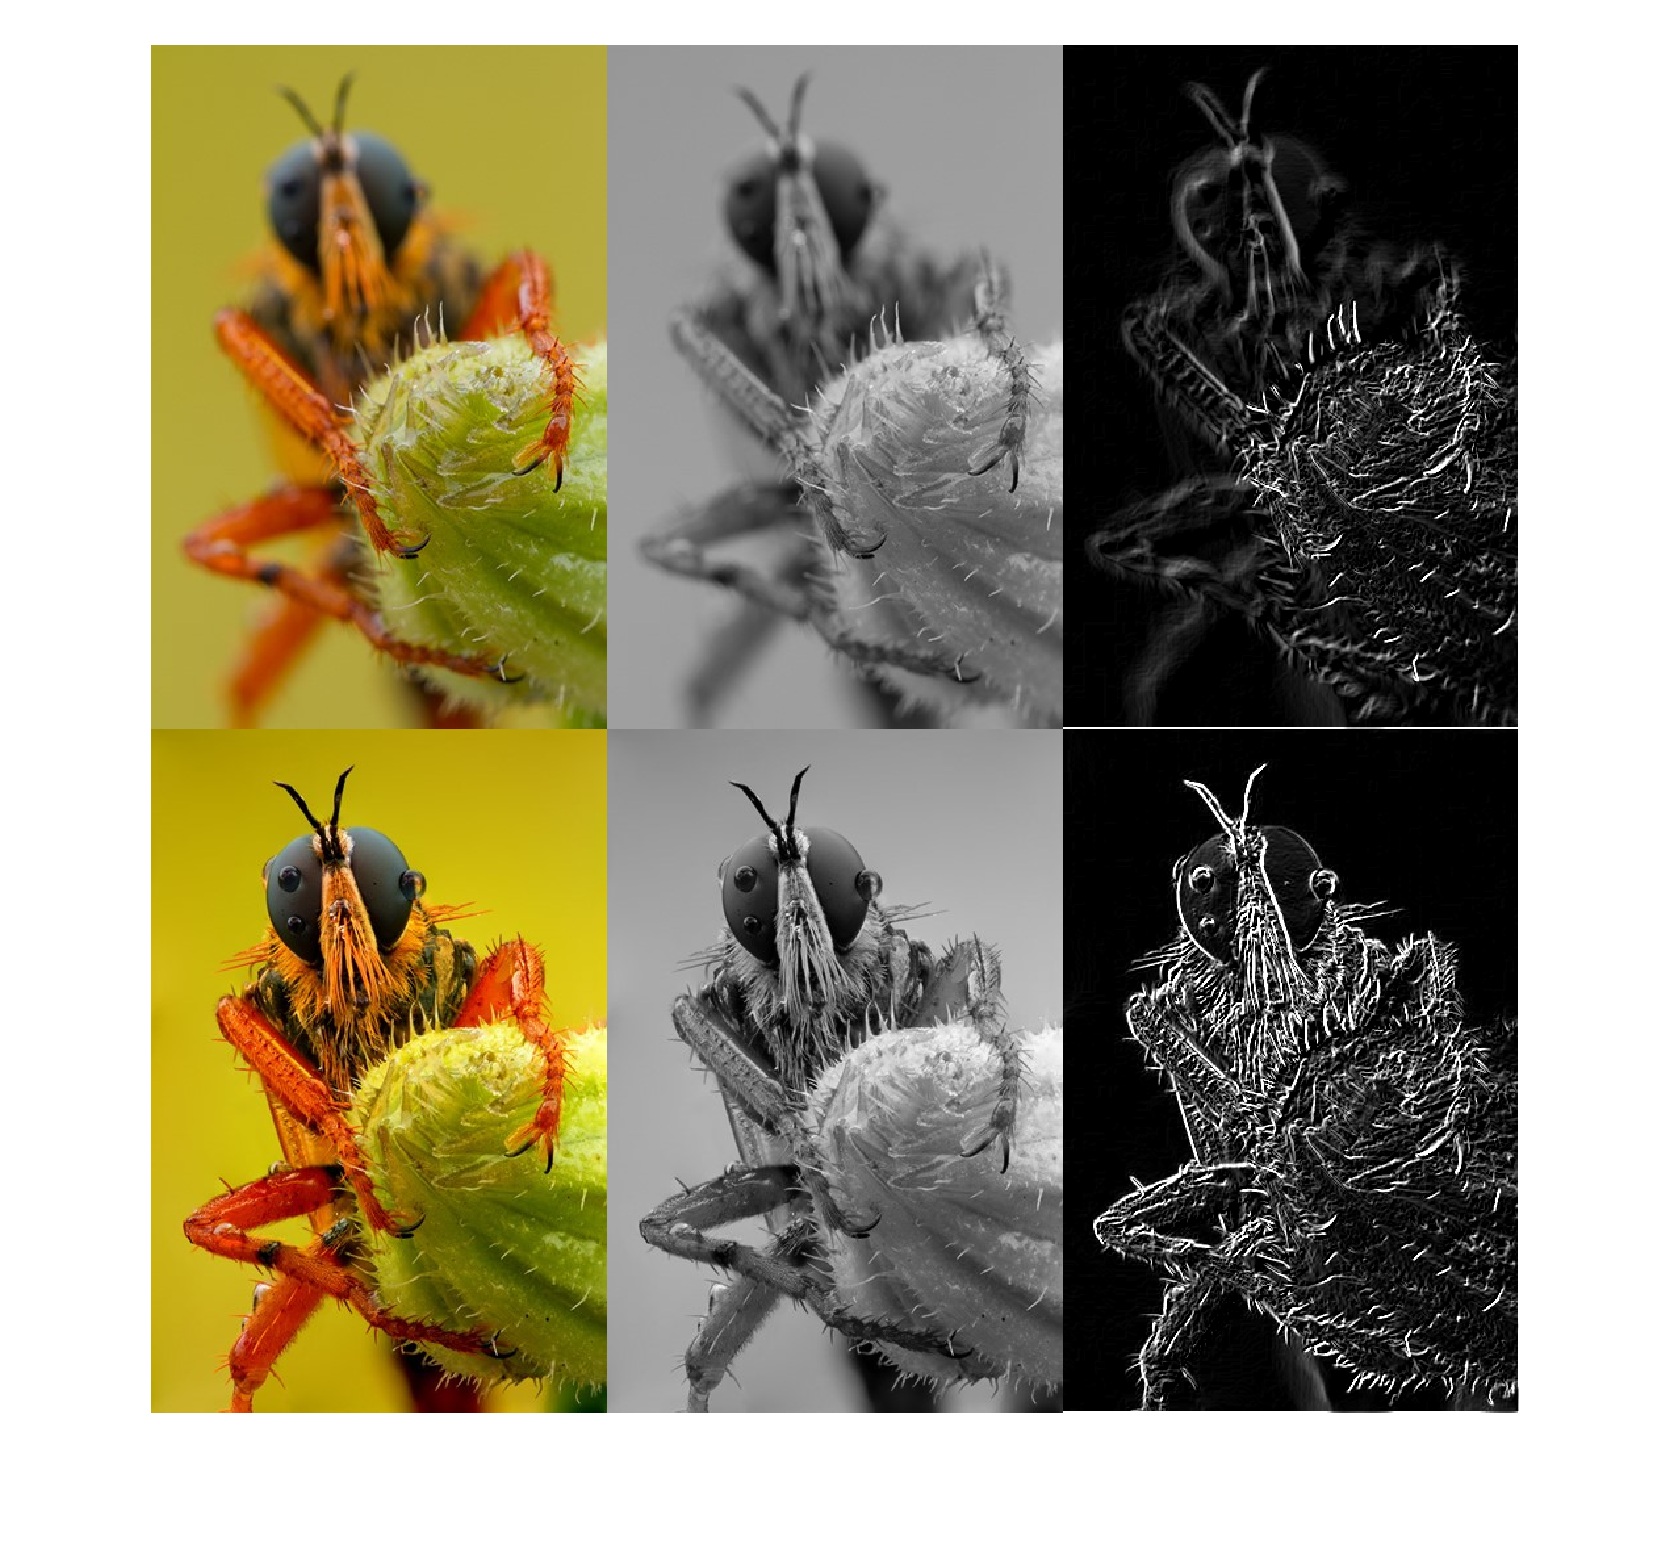

img1 = imread("image_9.1.jpeg");
img2 = imread("image_9.2.jpeg");

img1G = rgb2gray(img1);
img2G = rgb2gray(img2);

fimg1 = filtre_der(img1G);
fimg2 = filtre_der(img2G);
montage({img1, img1G, fimg1, img2, img2G, fimg2}, 'Size', [2 3])

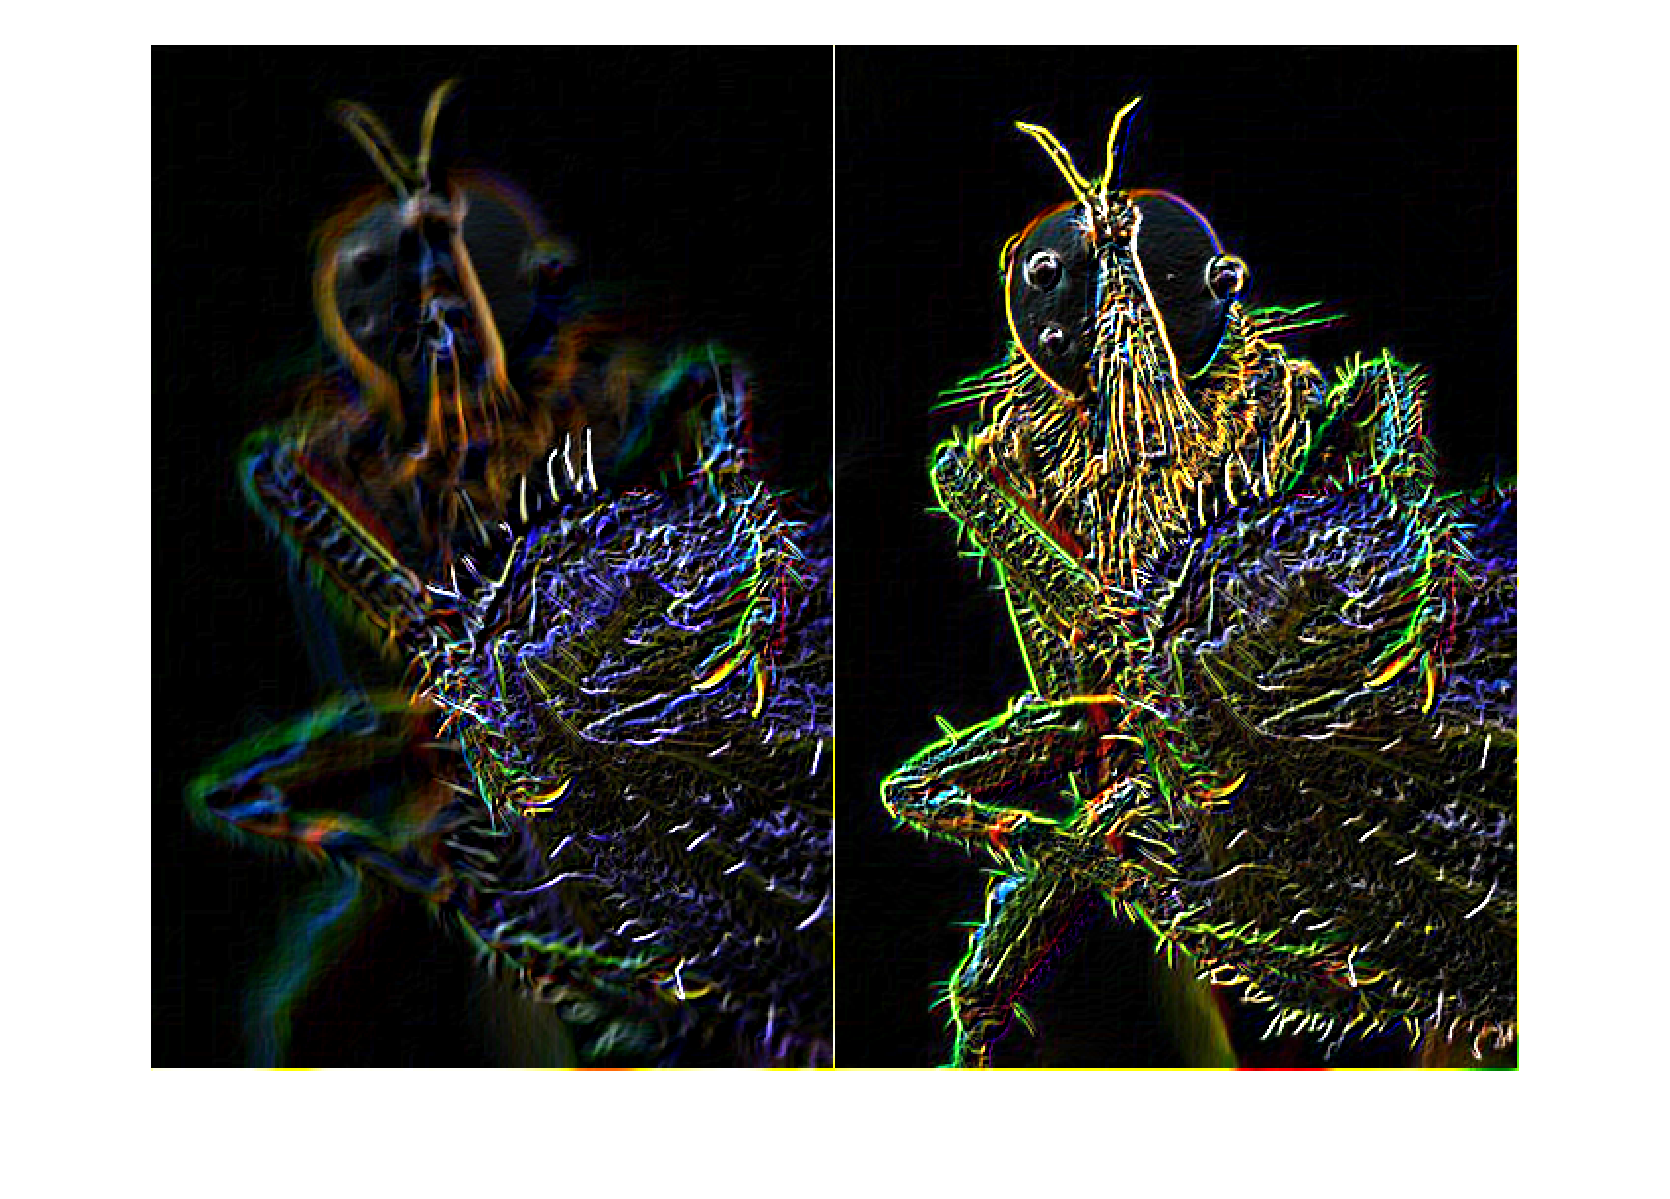


fimg1 = filtre_der(img1);
fimg2 = filtre_der(img2);
montage({fimg1, fimg2}, 'Size', [1 2])


m1 = get_m(fimg1)

m1 = int32
1855532

m2 = get_m(fimg2)

m2 = int32
3277256

function fimg = filtre_der(img)
h = fspecial('sobel');
Sx = imfilter(img, h);
Sy = imfilter(img, h');
fimg = imadd(Sx, Sy);
end

function m = get_m(img)
mida = size(img);
if mida(1) > mida(2)
   max_dist = mida(1) / 2;
else
   max_dist = mida(2) / 2;
end

x0 = mida(1) / 2;
y0 = mida(2) / 2;

m = 0;
for x1 = 1:mida(1)
    for y1 = 1:mida(2)
        dist = sqrt((x1 - x0)^2+(y1 - y0)^2);
        m = m + int32(img(x1, y1)) * (1 - dist/max_dist);
    end
end
end